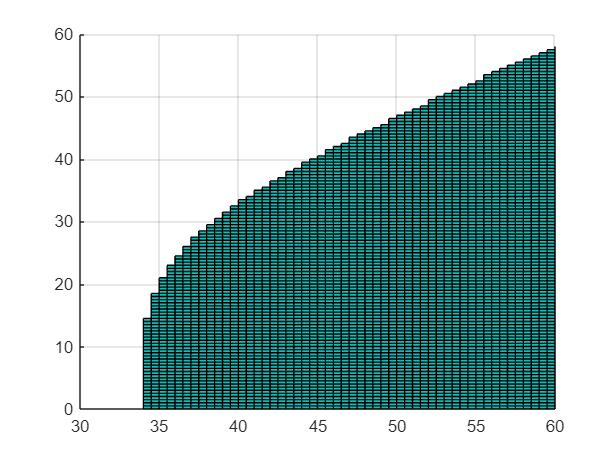

clc
clear all
syms D_o D_i
v = 0:0.5:100;
[D_o, D_i] = meshgrid(v);

g1 = -D_i <= 0;
g2 = D_o - 60 <= 0;
g3 = 1 + D_i - D_o <= 0;
g4 = 1289692.1869 - D_o.^4 + D_i.^4 <= 0;
g5 = 11697.8883.*D_o - D_o.^4 + D_i.^4 <= 0;

g1 = double(g1);
g2 = double(g2);
g3 = double(g3);
g4 = double(g4);
g5 = double(g5);

g1(g1==0) = NaN;
g2(g2==0) = NaN;
g3(g3==0) = NaN;
g4(g4==0) = NaN;
g5(g5==0) = NaN;

g = g1.*g2.*g3.*g4.*g5;
surf(D_o, D_i, g)
view(0, 90)

clc
clear all
syms D_o D_i
L = 2100;
ro = 7800.*(10.^-9);
W_h = pi.*L.*ro.*[(D_o./2).^2 - (D_i./2).^2];
Hf = hessian(W_h);

PM1 = Hf(1,1)

$$PM1 = -\frac{819\,\pi }{100000}$$

PM2 = det(Hf)

$$PM2 = -\frac{670761\,\pi^{2}}{10000000000}$$


PM1_test = subs(PM1,[D_o,D_i],[0.05,6])

$$PM1\_test = -\frac{819\,\pi }{100000}$$

PM2_test = subs(PM2,[D_o,D_i],[0.05,6])

$$PM2\_test = -\frac{670761\,\pi^{2}}{10000000000}$$

clc
clear all
syms D_o D_i u1 u2 u3 u4 u5 s1 s2 s3 s4 s5 L
L = 2100;
ro = 7800.*(10.^-9);

Lagrangian = (pi.*L.*ro.*[(D_o./2).^2 - (D_i./2).^2])+u1.*(-D_i + s1.^2)+u2.*(D_o - 60 + s2.^2)+u3.*(1 + D_i - D_o + s3.^2)+u4.*(1289692.1869 - D_o.^4 + D_i.^4 + s4.^2)+u5.*(11697.8883.*D_o - D_o.^4 + D_i.^4 + s5.^2);

eqn1 = s1.^2 >= 0;
eqn2 = s2.^2 >= 0;     
eqn3 = s3.^2 >= 0;     
eqn4 = s4.^2 >= 0;     
eqn5 = s5.^2 >= 0;     

eqn6 = diff(Lagrangian, 'D_o') == 0;
eqn7 = diff(Lagrangian, 'D_i') == 0;
eqn8 = diff(Lagrangian, 'u1') == 0;
eqn9 = diff(Lagrangian, 'u2') == 0;
eqn10 = diff(Lagrangian, 'u3') == 0;
eqn11 = diff(Lagrangian, 'u4') == 0;
eqn12 = diff(Lagrangian, 'u5') == 0;
eqn13 = diff(Lagrangian, 's1') == 0;
eqn14 = diff(Lagrangian, 's2') == 0;
eqn15 = diff(Lagrangian, 's3') == 0;
eqn16 = diff(Lagrangian, 's4') == 0;
eqn17 = diff(Lagrangian, 's5') == 0;

eqn18 = u1 >= 0;
eqn19 = u2 >= 0;
eqn20 = u3 >= 0;
eqn21 = u4 >= 0;
eqn22 = u5 >= 0;

eqns = [eqn1 eqn2 eqn3 eqn4 eqn5 eqn6 eqn7 eqn8 eqn9 eqn10 eqn11 eqn12 eqn13 eqn14 eqn15 eqn16 eqn17 eqn18 eqn19 eqn20 eqn21 eqn22];

s = solve(eqns);

D_o_min = vpa(s.D_o);
D_i_min = vpa(s.D_i);
u1_min = vpa(s.u1);
u2_min = vpa(s.u2);
u3_min = vpa(s.u3);
u4_min = vpa(s.u4);
u5_min = vpa(s.u5);
s1_min = vpa(s.s1);
s2_min = vpa(s.s2);
s3_min = vpa(s.s3);
s4_min = vpa(s.s4);
s5_min = vpa(s.s5);

Lagrangian_min = subs((pi.*L.*ro.*[(D_o./2).^2 - (D_i./2).^2])+u1.*(-D_i + s1.^2)+u2.*(D_o - 60 + s2.^2)+u3.*(1 + D_i - D_o + s3.^2)+u4.*(1289692.1869 - D_o.^4 + D_i.^4 + s4.^2)+u5.*(11697.8883.*D_o - D_o.^4 + D_i.^4 + s5.^2),{D_o,D_i,u1,u2,u3,u4,u5,s1,s2,s3,s4,s5},{D_o_min,D_i_min,u1_min,u2_min,u3_min,u4_min,u5_min,s1_min,s2_min,s3_min,s4_min,s5_min});

fprintf("D_o_min = %.8f\n",D_o_min(1))

D_o_min = 60.00000000


fprintf("D_i_min = %.8f\n",D_i_min(1))

D_i_min = 58.44812420


fprintf("Minimum of cost function = %f\n",Lagrangian_min(1))

Minimum of cost function = 2.364770


clc
clear all
syms D_o D_i u1 u2 u3 u4 u5 s1 s2 s3 s4 s5
L = 2100;
ro = 7800.*(10.^-9);

Lagrangian = (pi.*L.*ro.*[(D_o./2).^2 - (D_i./2).^2])+u1.*(-D_i + s1.^2)+u2.*(D_o - 60 + s2.^2)+u3.*(1 + D_i - D_o + s3.^2)+u4.*(1289692.1869 - D_o.^4 + D_i.^4 + s4.^2)+u5.*(11697.8883.*D_o - D_o.^4 + D_i.^4 + s5.^2);
             
gradL= gradient(Lagrangian);
s= subs(gradL,[u1,u2,u3,u4,u5],[0,0,0,0,0]);
te = vpasolve(s==0);

test = te.D_o(1)

$$test = 0$$

test = te.D_i(1)

$$test = 0$$

test = te.s1(1)

$$test = 0$$

test = te.s2(1)

$$test = -7.7459666924148337703585307995648$$

test = te.s3(1)

$$test = -1.0\,\mathrm{i}$$

test = te.s4(1)

$$test = -1135.6461539141494789535829008484\,\mathrm{i}$$

test = te.s5(1)

$$test = 0$$